# Assignment 2

# 190639B

clear;
close all;
clc;
load idealECG.mat;


## Data construction

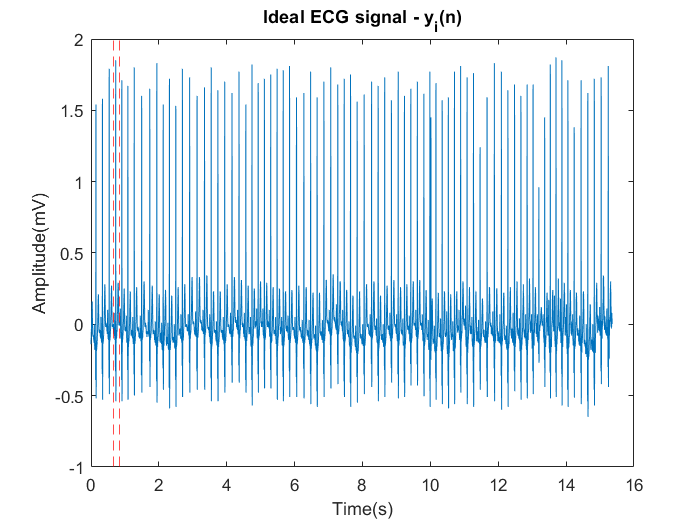


n=(0:length(idealECG)-1);
t=n/500;
SNR=10;
fs=50;

y_i=idealECG-mean(idealECG);
nwg=awgn(y_i,10,'measured')-y_i;
n50= 0.2* sin(2*pi*fs*t);

noise=nwg+n50;
xn=y_i+noise;

% Declare samples for part1
Y_start=335;
Y_stop=414;
X_start=413;
X_stop=432;

figure;
plot(t,y_i);
xline(Y_start/500,'--r');
xline(Y_stop/500,'--r');
title("Ideal ECG signal - y_i(n)");
ylabel("Amplitude(mV)");
xlabel("Time(s)");

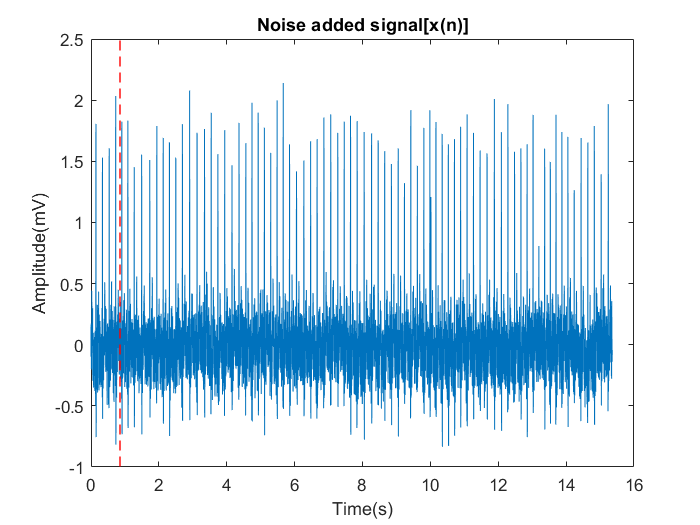


figure;
plot(t,xn);
xline(X_start/500,'--r');
xline(X_stop/500,'--r');
title("Noise added signal[x(n)]");
xlabel("Time(s)");
ylabel("Amplitude(mV)");

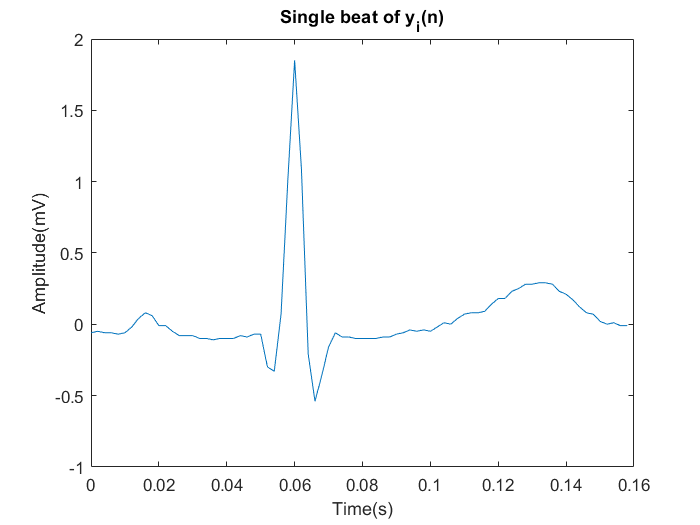


single_beat=y_i(:,Y_start:Y_stop);
figure;
plot((0:length(single_beat)-1)/500,single_beat);
title('Single beat of y_i(n)');
xlabel("Time(s)");
ylabel("Amplitude(mV)");

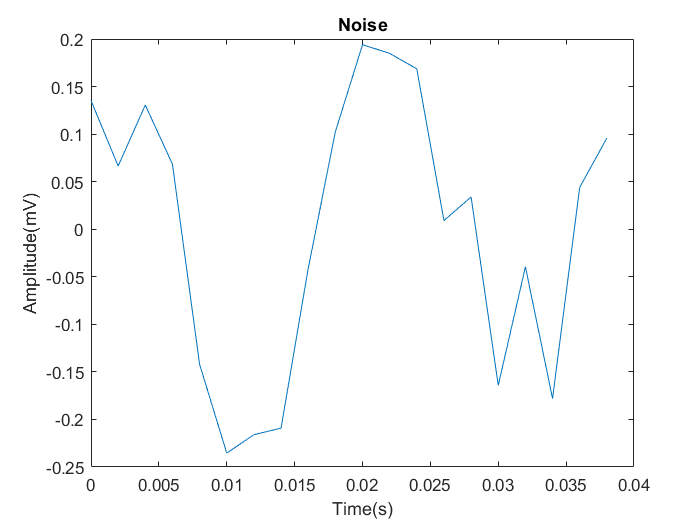


noise_signal=noise(:,X_start:X_stop);
figure;
plot((0:length(noise_signal)-1)/500,noise_signal);
title("Noise");
xlabel("Time(s)");
ylabel("Amplitude(mV)");

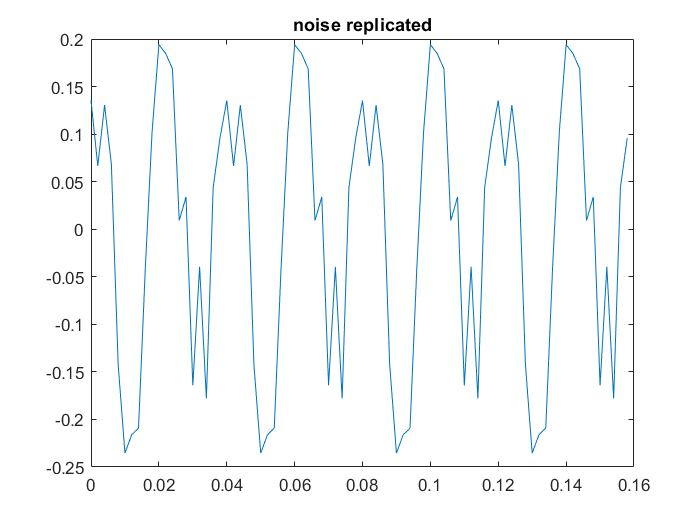


noise_replicated = repmat(noise_signal,[1,4]);
noise_replicated=noise_replicated(1:80);
plot((0:length(noise_replicated)-1)/500,noise_replicated);
title('noise replicated');

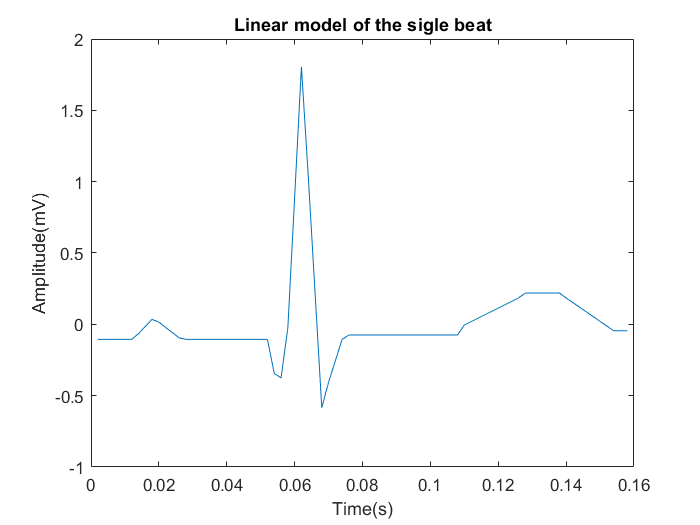

% Part 2 signal construction
[linear_model,time]=getLinearModel(Y_start,Y_stop,500);
plot(time,linear_model);
title('Linear model of the sigle beat');
xlabel('Time(s)');
ylabel('Amplitude(mV)');

### 1.1 Discrete-Time domain implimentation of Wiener filter


arbitrary_order=11;

%% With part 1
w1=wienerD(single_beat,noise_replicated,arbitrary_order);

%% With part 2

w2=wienerD(linear_model,noise_replicated,arbitrary_order);

fprintf ("The arbitary order is %d\n",arbitrary_order );

The arbitary order is 11


fprintf (" Weights for Part 1 : \n" );

 Weights for Part 1 : 


disp(w1);

    0.7600
    0.3535
   -0.0927
   -0.1393
    0.0063
    0.1604
    0.1722
    0.0912
    0.0431
    0.0300
    0.0578



fprintf (" Weights for Part 2 : \n");

 Weights for Part 2 : 


disp(w2);

    0.6809
    0.2967
   -0.0471
   -0.2004
   -0.0850
    0.0785
    0.0932
    0.0614
    0.0067
   -0.0037
   -0.0099



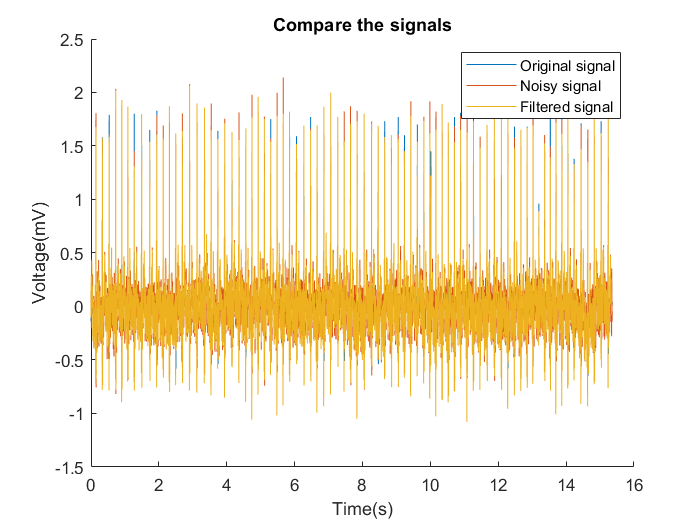

new_filtered_signal=wienerFilteredSignal(xn,w1);
figure;
hold on;
plot(t,y_i,t,xn,t,new_filtered_signal);
legend('Original signal','Noisy signal','Filtered signal');
hold off;
title("Compare the signals");
ylabel('Voltage(mV)');
xlabel('Time(s)');

range_of_filter_order=70;
mean_sq_error1=zeros(1,range_of_filter_order);
mean_sq_error2=zeros(1,range_of_filter_order);

noisy_signal=xn(:,Y_start:Y_stop);
for order=2:range_of_filter_order
    w1=wienerD(single_beat,noise_replicated,order);
    w2=wienerD(linear_model,noise_replicated,order);
    part1_filtered=wienerFilteredSignal(noisy_signal,w1);
    part2_filtered=wienerFilteredSignal(noisy_signal,w2);
    mean_sq_error1(order)=immse(single_beat,part1_filtered);
    mean_sq_error2(order)=immse(single_beat,part2_filtered);
end

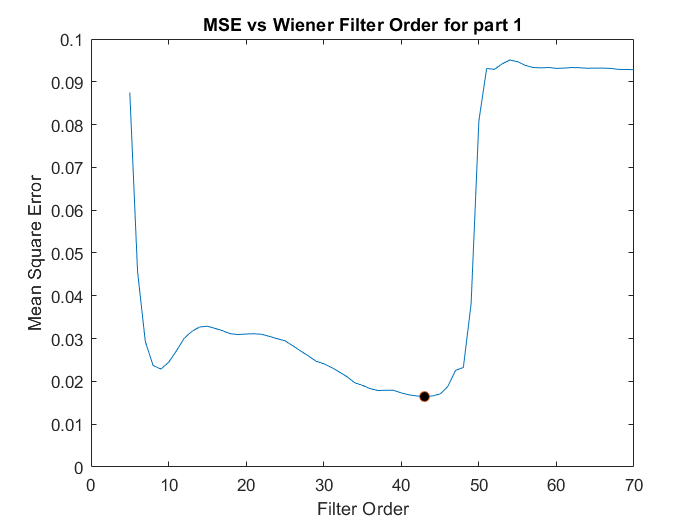

figure;
plot(mean_sq_error1)
hold on;
[minimum_MSE1, corresponding_order] = min(mean_sq_error1(2:70));
scatter(corresponding_order+1, minimum_MSE1, 'MarkerFaceColor','k');
title('MSE vs Wiener Filter Order for part 1')
xlabel('Filter Order')
ylabel('Mean Square Error');
hold off;

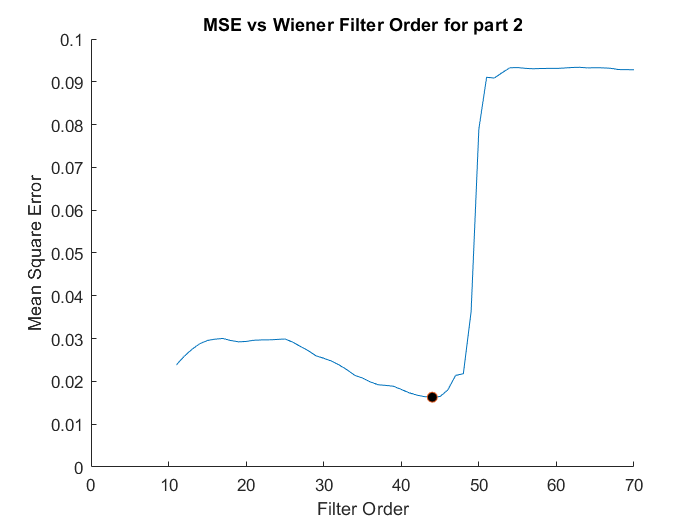

figure;
hold on;
plot(mean_sq_error2)
[minimum_MSE2, corresponding_order2] = min(mean_sq_error2(2:70));
scatter(corresponding_order2+1, minimum_MSE2, 'MarkerFaceColor','k');
hold off;
title('MSE vs Wiener Filter Order for part 2')
xlabel('Filter Order')
ylabel('Mean Square Error');

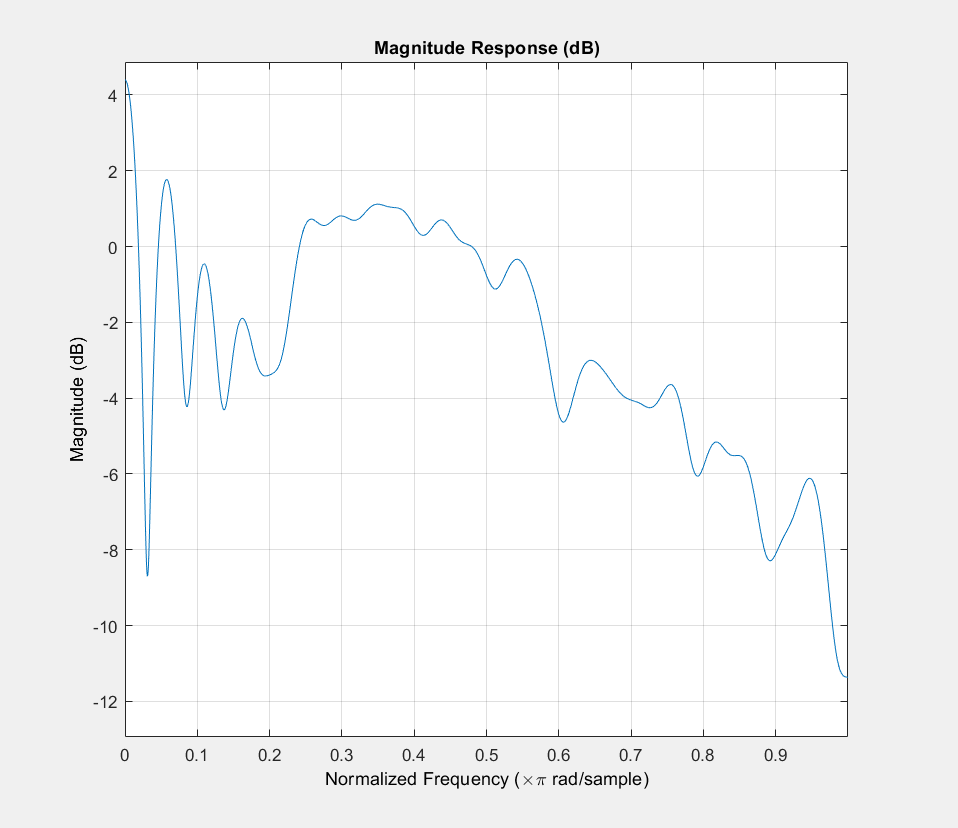

%Part 1
wienerWeights_for_optimum_order1 = wienerD(single_beat, noise_replicated, corresponding_order+1);

% Obtaining the magnitude response of the filter
fvtool(wienerWeights_for_optimum_order1,1);

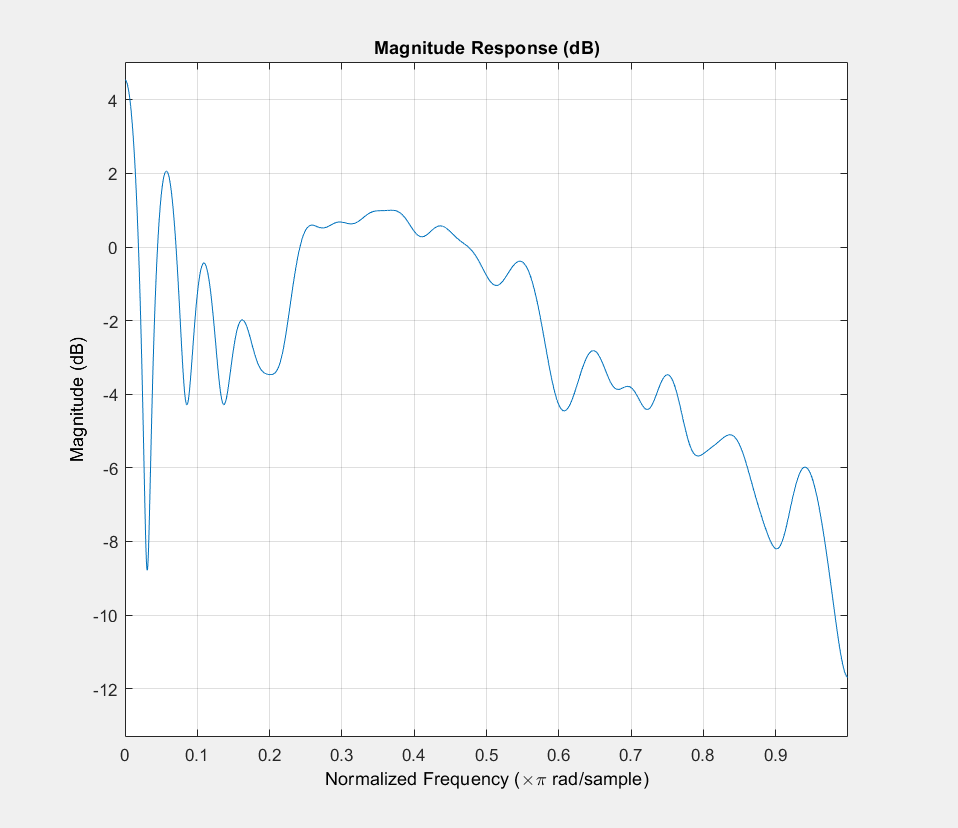



%Part 2
wienerWeights_for_optimum_order2 = wienerD(single_beat, noise_replicated, corresponding_order2+1);

% Obtaining the magnitude response of the filter
fvtool(wienerWeights_for_optimum_order2,1);

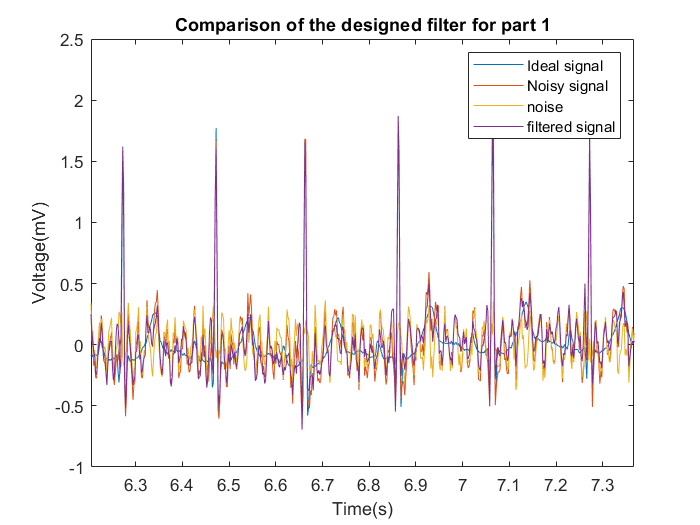

%Part 1
optimum_filtered_signal=wienerFilteredSignal(xn,wienerWeights_for_optimum_order1);
figure;
plot(t,y_i,t,xn,t,noise,t,optimum_filtered_signal);
legend('Ideal signal','Noisy signal','noise','filtered signal');
title('Comparison of the designed filter for part 1');
xlabel('Time(s)');
ylabel('Voltage(mV)');

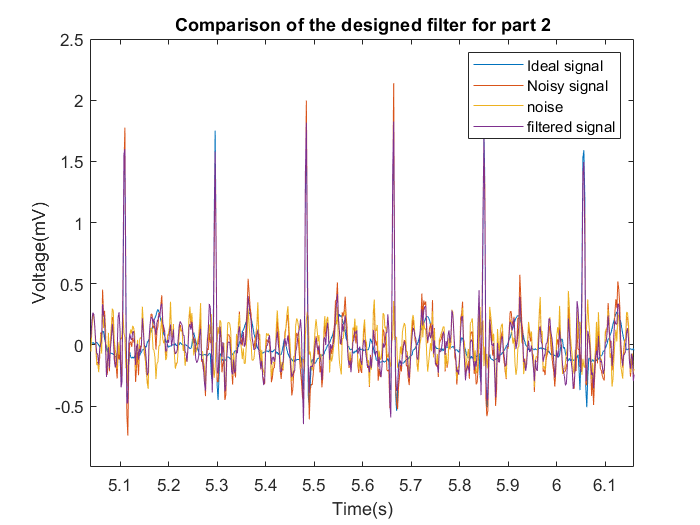


%Part 2
optimum_filtered_signal2=wienerFilteredSignal(xn,wienerWeights_for_optimum_order2);
figure;
plot(t,y_i,t,xn,t,noise,t,optimum_filtered_signal2);
legend('Ideal signal','Noisy signal','noise','filtered signal');
title('Comparison of the designed filter for part 2');
xlabel('Time(s)');
ylabel('Voltage(mV)');

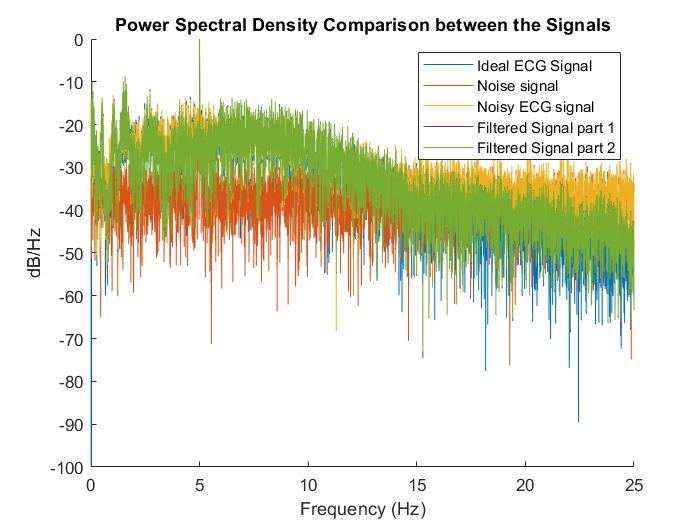

[spectra_1,freq_1] = periodogram(y_i,[],[],fs);
[spectra_2,freq_2] = periodogram(noise,[],[],fs);
[spectra_3,freq_3] = periodogram(xn,[],[],fs);
[spectra_4,freq_4] = periodogram(optimum_filtered_signal,[],[],fs);
[spectra_5,freq_5] = periodogram(optimum_filtered_signal2,[],[],fs);

figure;
hold on;
plot(freq_1,10*log10(spectra_1))
plot(freq_2,10*log10(spectra_2))
plot(freq_3,10*log10(spectra_3))
plot(freq_4,10*log10(spectra_4))
plot(freq_5,10*log10(spectra_5))
hold off;
ylim([-100,0])

legend('Ideal ECG Signal','Noise signal', 'Noisy ECG signal','Filtered Signal part 1','Filtered Signal part 2')
title('Power Spectral Density Comparison between the Signals')
xlabel('Frequency (Hz)')
ylabel('dB/Hz');

### 1.2 Frequency domain analysis

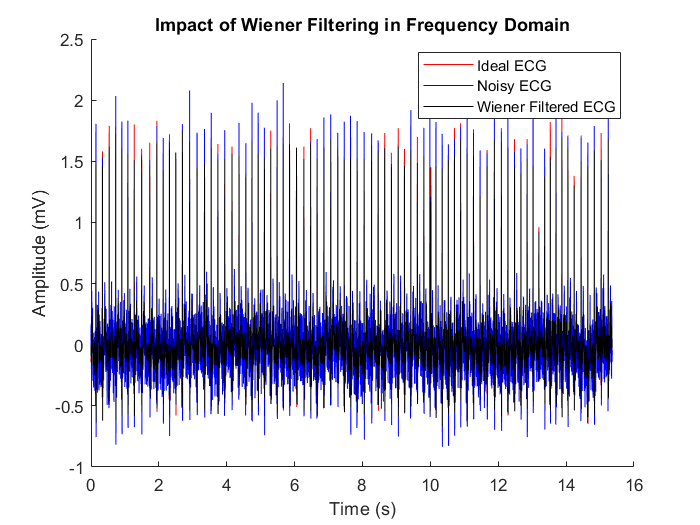


[FreqDomainFilt_signal, w_fd] = wienerFD(y_i, noise, xn);

% Plotting the signals in time domain
figure();
hold on
plot(t, y_i,'r')
plot(t, xn,'b')
plot(t, FreqDomainFilt_signal,'k')
hold off
legend('Ideal ECG','Noisy ECG','Wiener Filtered ECG')
title(['Impact of Wiener Filtering in Frequency Domain'])
xlabel('Time (s)')
ylabel('Amplitude (mV)');

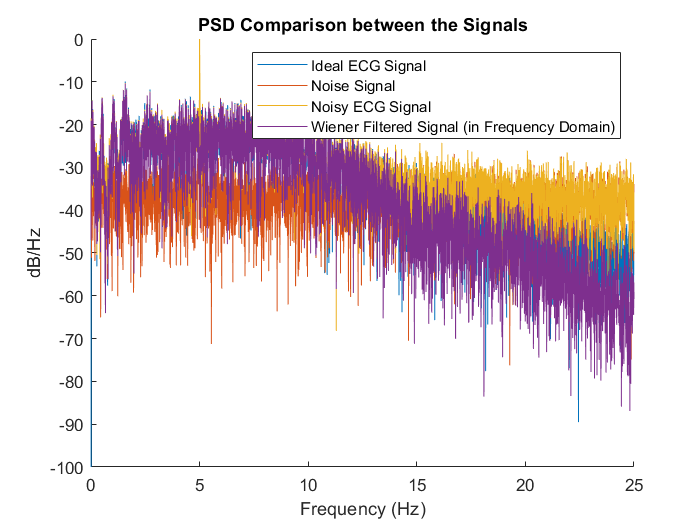


[spectra_1_new, freq_1_new] = periodogram(y_i,[],[],fs);
[spectra_2_new, freq_2_new] = periodogram(noise,[],[],fs);
[spectra_3_new, freq_3_new] = periodogram(xn,[],[],fs);
[spectra_4_new, freq_4_new] = periodogram(FreqDomainFilt_signal,[],[],fs);

% Plotting the PSDs of the signals
figure();
hold on;
plot(freq_1_new, 10*log10(spectra_1_new))
plot(freq_2_new, 10*log10(spectra_2_new))
plot(freq_3_new, 10*log10(spectra_3_new))
plot(freq_4_new, 10*log10(spectra_4_new))
hold off;
ylim([-100 0])
legend('Ideal ECG Signal','Noise Signal','Noisy ECG Signal','Wiener Filtered Signal (in Frequency Domain)')
title('PSD Comparison between the Signals')
xlabel('Frequency (Hz)')
ylabel('dB/Hz');

%1.2.2
MSE_freq_domain = immse(FreqDomainFilt_signal, y_i);
fprintf('Mean squared error of part 1: %f.5\n',minimum_MSE1);

Mean squared error of part 1: 0.016452.5


fprintf('Mean squared error of part 2: %f.5\n',minimum_MSE2);

Mean squared error of part 2: 0.016304.5


fprintf('Mean squared error after frequency domain anlysis: %f.5\n',MSE_freq_domain);

Mean squared error after frequency domain anlysis: 0.003340.5


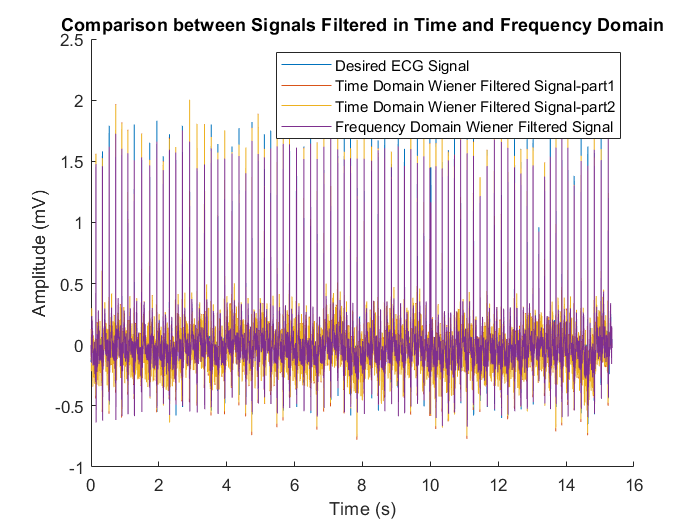


% Plotting the signals
figure('Name', 'Comparison between the Filtered Signals')
hold on;
plot(t,y_i)
plot(t,optimum_filtered_signal)
plot(t,optimum_filtered_signal2)
plot(t,FreqDomainFilt_signal)
hold off;

legend('Desired ECG Signal','Time Domain Wiener Filtered Signal-part1', 'Time Domain Wiener Filtered Signal-part2','Frequency Domain Wiener Filtered Signal')
title(['Comparison between Signals Filtered in Time and Frequency Domain'])
xlabel('Time (s)')
ylabel('Amplitude (mV)');

### 1.3 Effect on non-stationary noise on the Wiener filtering

% Data construction
t1 = t(1:length(t)/2);
t2 = t(length(t)/2+1:end);

n50_new = 0.2*sin(2*pi*50*t1);
n100 = 0.3*sin(2*pi*100*t2);
tot_non_white_noise=[n50_new n100];
nwg_new = awgn(y_i,10,'measured')-y_i;
Total_noise = nwg_new + tot_non_white_noise;

xn_new = y_i+Total_noise;

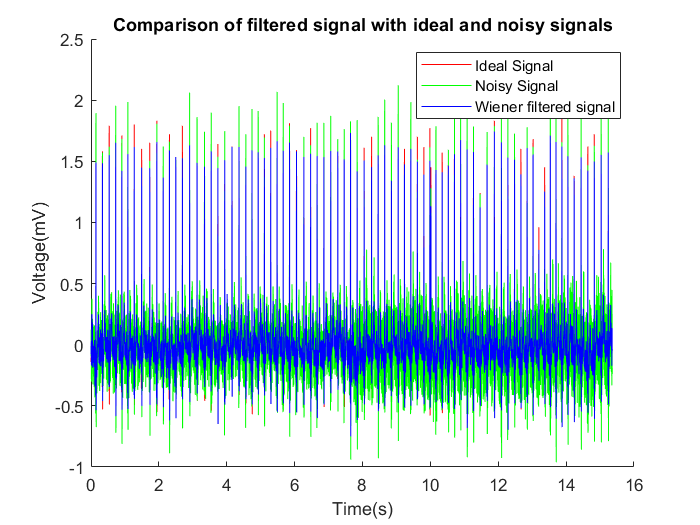

% 1.3 (a) 
% Using 1.2 
[FreqDomainFilt_signal_new, w_fd_new] = wienerFD(y_i, Total_noise, xn_new);

%1.3 (b)
figure;
hold on;
plot(t,y_i,'r')
plot(t,xn_new,'g')
plot(t,FreqDomainFilt_signal_new,'b');
hold off;
title("Comparison of filtered signal with ideal and noisy signals");
xlabel('Time(s)');
ylabel("Voltage(mV)");
legend('Ideal Signal','Noisy Signal','Wiener filtered signal')

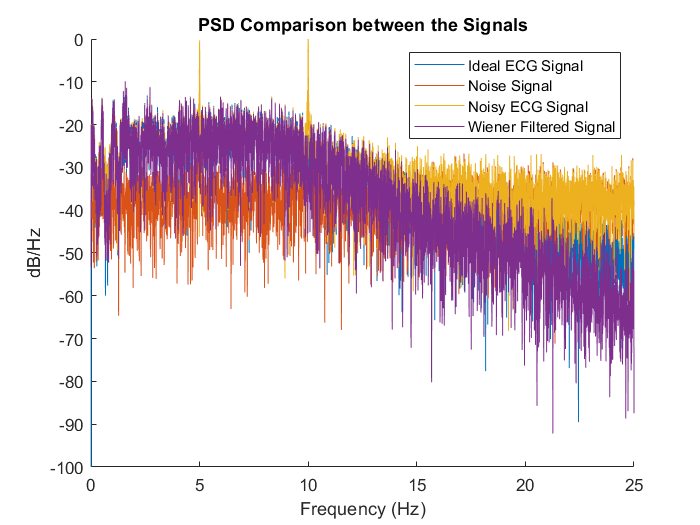


[spectra_1_new, freq_1_new] = periodogram(y_i,[],[],fs);
[spectra_2_new, freq_2_new] = periodogram(Total_noise,[],[],fs);
[spectra_3_new, freq_3_new] = periodogram(xn_new,[],[],fs);
[spectra_4_new, freq_4_new] = periodogram(FreqDomainFilt_signal_new,[],[],fs);

% Plotting the PSDs of the signals
figure();
hold on;
plot(freq_1_new, 10*log10(spectra_1_new))
plot(freq_2_new, 10*log10(spectra_2_new))
plot(freq_3_new, 10*log10(spectra_3_new))
plot(freq_4_new, 10*log10(spectra_4_new))
hold off;
ylim([-100 0])
legend('Ideal ECG Signal','Noise Signal','Noisy ECG Signal','Wiener Filtered Signal')
title('PSD Comparison between the Signals')
xlabel('Frequency (Hz)')
ylabel('dB/Hz');